# Actividad 9

### Ximena Ortiz Gomez A01735100

Ejercicio con control tipo Pure Pursuit

%% EXAMPLE: Differential drive vehicle following waypoints using the 
% Pure Pursuit algorithm
%
% Copyright 2018-2019 The MathWorks, Inc.

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.01;               % Sample time [s]
tVec = 0:sampleTime:101;         % Time array

initPose = [-1.6624128100854; 2.3274916900911;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
%% Importar waypoints desde Excel

% Leer la primera columna del archivo Excel como texto
datos = readcell("puntos.xlsx");

% Tomar solo la primera columna
datos = datos(:,1);

% Eliminar filas vacías
datos = datos(~cellfun(@(x) isempty(x) || (isstring(x) && strlength(x)==0), datos));

% Convertir a string para procesar
datos = string(datos);

% Quitar paréntesis
datos = erase(datos, "(");
datos = erase(datos, ")");

% Separar X y Y usando la coma
partes = split(datos, ",");

% Convertir a números
x = str2double(strtrim(partes(:,1)));
y = str2double(strtrim(partes(:,2)));

% Crear matriz de waypoints
waypoints = [x y];

% Revisar que se importaron bien
disp("Waypoints importados:");
disp(waypoints);

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.20;
controller.DesiredLinearVelocity = 0.5;
controller.MaxAngularVelocity = 4;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef)
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

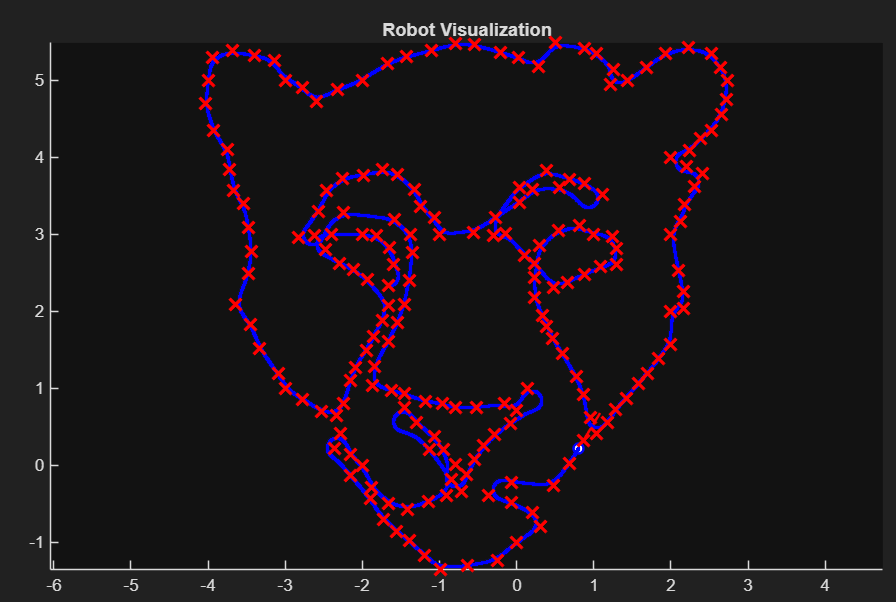

Ejercicio con codigo de control en lazo cerrado

%Limpieza de pantalla
clc
clear all
close all

%% 1. TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf = 500;
ts = 0.05;
t  = 0:ts:tf;
N  = length(t);

%% 2. LECTURA DE WAYPOINTS DESDE EXCEL %%%%%%%%%%%%%%%%%%%%%%%%%%%%
archivo = 'puntos.xlsx';

% Leer como celdas de texto
rawData = readcell(archivo);

numPuntos = size(rawData, 1);
wp_xy = zeros(numPuntos, 2);

for i = 1:numPuntos
    texto = rawData{i};
    % Convertir a char por si viene como string
    if isstring(texto)
        texto = char(texto);
    end
    % Quitar paréntesis y espacios
    texto = strrep(texto, '(', '');
    texto = strrep(texto, ')', '');
    % Separar por coma
    partes = split(texto, ',');
    wp_xy(i, 1) = str2double(partes{1});
    wp_xy(i, 2) = str2double(partes{2});
end

tolerancia = 0.12;
waypoints  = [wp_xy, tolerancia * ones(numPuntos, 1)];

numWP = size(waypoints, 1);
wpIdx = 1;

fprintf('Se cargaron %d waypoints desde %s\n', numWP, archivo);

%% 3. CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Usamos el primer waypoint del Excel como posición inicial
x1(1)   = waypoints(1, 1);
y1(1)   = waypoints(1, 2);
phi(1)  = pi/2;
hx(1)   = x1(1);
hy(1)   = y1(1);

%% 4. PARÁMETROS CONTROL ADAPTATIVO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Kv0     = 0.8;
Kw0     = 1.5;
alpha_v = 0.08;
alpha_w = 0.05;

Kv_max  = 2.5;   Kw_max = 3.5;
Kv_min  = 0.3;   Kw_min = 0.5;

v_max   = 1.2;
w_max   = 1.5;

v_prev  = 0;
w_prev  = 0;
beta    = 0.85;

%% 5. BUCLE DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for k = 1:N

    % --- Waypoint activo ---
    hxd = waypoints(wpIdx, 1);
    hyd = waypoints(wpIdx, 2);
    tol = waypoints(wpIdx, 3);

    %% a) ERRORES
    hxe(k) = hxd - hx(k);
    hye(k) = hyd - hy(k);

    Error(k) = sqrt(hxe(k)^2 + hye(k)^2);

    phi_d  = atan2(hye(k), hxe(k));
    e_phi  = phi_d - phi(k);
    e_phi  = atan2(sin(e_phi), cos(e_phi));   % normalización angular

    %% b) GANANCIAS AUTO-SINTONIZABLES
    Kv(k) = Kv0 + alpha_v * Error(k);
    Kw(k) = Kw0 + alpha_w * abs(e_phi);

    Kv(k) = min(max(Kv(k), Kv_min), Kv_max);
    Kw(k) = min(max(Kw(k), Kw_min), Kw_max);

    %% c) CONTROLADOR
    v_raw = Kv(k) * Error(k);
    v_raw = v_raw * cos(e_phi);       % reduce v si hay mucho error angular
    w_raw = Kw(k) * e_phi;

    %% d) SATURACIÓN DE VELOCIDADES
    v_raw = max(min(v_raw,  v_max), -v_max);
    w_raw = max(min(w_raw,  w_max), -w_max);

    %% e) FILTRO SUAVIZANTE
    v(k) = beta * v_prev + (1 - beta) * v_raw;
    w(k) = beta * w_prev + (1 - beta) * w_raw;
    v_prev = v(k);
    w_prev = w(k);

    %% f) CAMBIO DE WAYPOINT
    wpLog(k) = wpIdx;
    if Error(k) <= tol && wpIdx < numWP
        wpIdx = wpIdx + 1;
        v_prev = 0;
        w_prev = 0;
    end

    %% g) MODELO CINEMÁTICO
    phi(k+1)  = phi(k)  + w(k) * ts;
    xp1       = v(k) * cos(phi(k));
    yp1       = v(k) * sin(phi(k));
    x1(k+1)   = x1(k)  + xp1 * ts;
    y1(k+1)   = y1(k)  + yp1 * ts;
    hx(k+1)   = x1(k+1);
    hy(k+1)   = y1(k+1);
end

%% 6. SIMULACIÓN 2D EN EL PLANO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
scene = figure;
set(scene, 'Color', 'white');
set(gca,   'FontWeight', 'bold');
sizeScreen = get(0, 'ScreenSize');
set(scene, 'position', sizeScreen);
grid on; box on; axis equal;
xlabel('x [m]'); ylabel('y [m]');
title('Trayectoria del robot - Control en lazo cerrado');

% Límites automáticos según los waypoints (con margen)
margen = 1;
xmin = min(waypoints(:,1)) - margen;  xmax = max(waypoints(:,1)) + margen;
ymin = min(waypoints(:,2)) - margen;  ymax = max(waypoints(:,2)) + margen;
axis([xmin xmax ymin ymax]);

hold on;

% Dibujar todos los waypoints como puntos azules
plot(waypoints(:,1), waypoints(:,2), 'b.', 'MarkerSize', 12);
% Posición inicial (verde) y final deseada (negro)
plot(waypoints(1,1),   waypoints(1,2),   'go', 'MarkerSize', 10, 'LineWidth', 2);
plot(waypoints(end,1), waypoints(end,2), 'ks', 'MarkerSize', 10, 'LineWidth', 2);

% Inicialización de handles para la animación
H_traj  = plot(hx(1), hy(1), 'r', 'LineWidth', 2);     % trayectoria recorrida
H_robot = plot(x1(1), y1(1), 'bo', 'MarkerSize', 8, ...
               'MarkerFaceColor', 'b');                 % robot
H_head  = plot([x1(1) x1(1)+0.3*cos(phi(1))], ...
               [y1(1) y1(1)+0.3*sin(phi(1))], ...
               'b-', 'LineWidth', 2);                   % flecha de orientación

legend('Waypoints', 'Inicio', 'Fin', 'Trayectoria', 'Robot', ...
       'Location', 'bestoutside');

%% Animación 2D
step = 5;   % saltar muestras para que la animación corra más fluida
for k = 1:step:N
    delete(H_traj); delete(H_robot); delete(H_head);

    H_traj  = plot(hx(1:k), hy(1:k), 'r', 'LineWidth', 2);
    H_robot = plot(x1(k), y1(k), 'bo', 'MarkerSize', 8, ...
                   'MarkerFaceColor', 'b');
    H_head  = plot([x1(k) x1(k)+0.3*cos(phi(k))], ...
                   [y1(k) y1(k)+0.3*sin(phi(k))], ...
                   'b-', 'LineWidth', 2);

    title(sprintf('WP activo: %d/%d  |  Error: %.3f m', ...
                  wpLog(k), numWP, Error(k)));
    pause(ts);
end

%% 7. GRÁFICAS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph = figure;
set(graph, 'position', sizeScreen);

subplot(4,1,1)
plot(t, v, 'b', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'); ylabel('[m/s]'); legend('Velocidad lineal');

subplot(4,1,2)
plot(t, w, 'g', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'); ylabel('[rad/s]'); legend('Velocidad angular');

subplot(4,1,3)
plot(t, Error, 'r', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'); ylabel('[m]'); legend('Error de posición');

subplot(4,1,4)
stairs(t, wpLog, 'k', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'); ylabel('Índice'); legend('Waypoint activo');
ylim([0.5, numWP + 0.5]);